#  Question1

%(a)
%x1~N(x1,p1)=N([125;125],[10^2 0;0 5^2])
%x2~N(x2,p2)=N([-25;125],[10^2 0;0 5^2])
%x3~N(x3,p3)=N([60;60],[10^2 0;0 5^2])
s1=[0 100]';s2=[100 ,0]';
P_phi=(0.1*pi/180)^2*eye(2);
h = @(x) dualBearingMeasurement(x, s1, s2);
mean1=[125;125];P1=[10^2 0;0 5^2];N=10000;
mean2=[-25;125];P2=[10^2 0;0 5^2];
mean3=[60;60];P3=[10^2 0;0 5^2];

X1=mvnrnd(mean1,P1,N)';
X2=mvnrnd(mean2,P2,N)';
X3=mvnrnd(mean3,P3,N)';
Y1 = genNonLinearMeasurementSequence(X1, h, P_phi);
[mu_y1, Sigma_y1] = approxGaussianTransform(Y1)

mu_y1 =     0.1989
    1.3743


Sigma_y1 =     0.0018    0.0015
    0.0015    0.0059


Y2 = genNonLinearMeasurementSequence(X2, h, P_phi);
[mu_y2, Sigma_y2] = approxGaussianTransform(Y2)

mu_y2 =     2.3269
    2.3551


Sigma_y2 =     0.0557    0.0104
    0.0104    0.0020


Y3 = genNonLinearMeasurementSequence(X3, h, P_phi);
[mu_y3, Sigma_y3] = approxGaussianTransform(Y3)

mu_y3 =    -0.5934
    2.1499


Sigma_y3 =     0.0099   -0.0113
   -0.0113    0.0152


%(b)
%EKF
disp('****************************************************************************************************')

****************************************************************************************************


[EKFmean_y1,EKFP_y1] = nonLinKFprediction(mean1, P1,h, P_phi, 'EKF');
[EKFmean_y2,EKFP_y2] = nonLinKFprediction(mean2, P2, h, P_phi, 'EKF')

EKFmean_y2 =     2.3562
    2.3562


EKFP_y2 =     0.0500    0.0100
    0.0100    0.0020


[EKFmean_y3,EKFP_y3] = nonLinKFprediction(mean3, P3,h, P_phi, 'EKF')

EKFmean_y3 =    -0.5880
    2.1588


EKFP_y3 =     0.0092   -0.0111
   -0.0111    0.0148


%UKF
disp('****************************************************************************************************')

****************************************************************************************************


[UKFmean_y1,UKFP_y1] = nonLinKFprediction(mean1, P1, h, P_phi, 'UKF')

UKFmean_y1 =     0.1983
    1.3743


UKFP_y1 =     0.0017    0.0015
    0.0015    0.0059


[UKFmean_y2,UKFP_y2] = nonLinKFprediction(mean2, P2, h, P_phi, 'UKF')

UKFmean_y2 =     2.3269
    2.3550


UKFP_y2 =     0.0600    0.0108
    0.0108    0.0020


[UKFmean_y3,UKFP_y3] = nonLinKFprediction(mean3, P3, h, P_phi, 'UKF')

UKFmean_y3 =    -0.5949
    2.1524


UKFP_y3 =     0.0099   -0.0112
   -0.0112    0.0151


%CKF
disp('****************************************************************************************************')

****************************************************************************************************


[CKFmean_y1,CKFP_y1] = nonLinKFprediction(mean1, P1, h, P_phi, 'CKF')

CKFmean_y1 =     0.1983
    1.3743


CKFP_y1 =     0.0017    0.0015
    0.0015    0.0059


[CKFmean_y2,CKFP_y2] = nonLinKFprediction(mean2, P2, h, P_phi, 'CKF')

CKFmean_y2 =     2.3265
    2.3550


CKFP_y2 =     0.0566    0.0105
    0.0105    0.0020


[CKFmean_y3,CKFP_y3] = nonLinKFprediction(mean3, P3, h, P_phi, 'CKF')

CKFmean_y3 =    -0.5948
    2.1523


CKFP_y3 =     0.0097   -0.0112
   -0.0112    0.0150


%(c)
% mu_set=[mu_y1 EKFmean_y1 UKFmean_y1 CKFmean_y1;
%         mu_y2 EKFmean_y2 UKFmean_y2 CKFmean_y2;
%         mu_y3 EKFmean_y3 UKFmean_y3 CKFmean_y3];
% Sigma_set1=[Sigma_y1 EKFP_y1 UKFP_y1 CKFP_y1;
%             Sigma_y2 EKFP_y2 UKFP_y2 CKFP_y2;
%             Sigma_y3 EKFP_y3 UKFP_y3 CKFP_y3;];

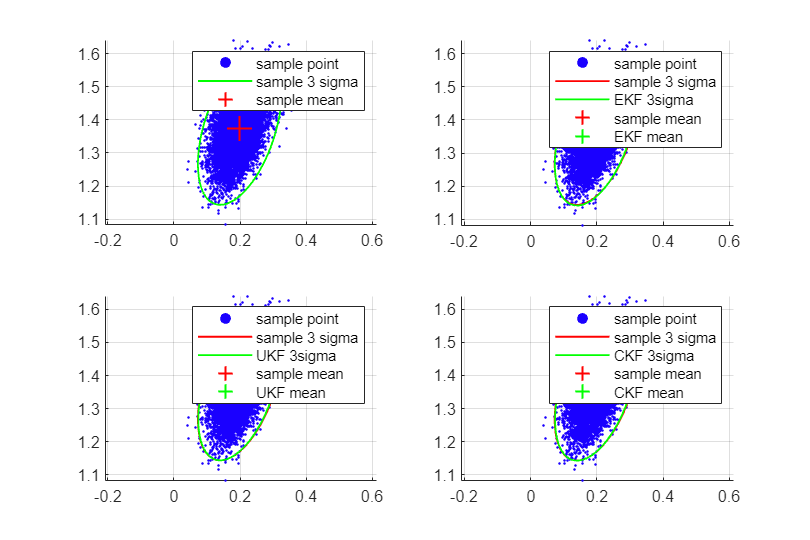

figure('Position',[300 300 600 400]);hold on;
covEllipse1 = sigmaEllipse2D(mu_y1, Sigma_y1, 3, 100);
covEllipse2 = sigmaEllipse2D(EKFmean_y1, EKFP_y1, 3, 100);
covEllipse3 = sigmaEllipse2D(UKFmean_y1, UKFP_y1, 3, 100);
covEllipse4 = sigmaEllipse2D(CKFmean_y1, CKFP_y1, 3, 100);
subplot(2,2,1)
scatter(Y1(1,:),Y1(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'-g','LineWidth',1);hold on;
plot(mu_y1(1),mu_y1(2),'+r','MarkerSize',14,'LineWidth',1)
axis equal
grid on
legend('sample point','sample 3 sigma','sample mean')
subplot(2,2,2)
scatter(Y1(1,:),Y1(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse2(1,:),covEllipse2(2,:),'-g','LineWidth',1);
plot(mu_y1(1),mu_y1(2),'+r','MarkerSize',14,'LineWidth',1)
plot(EKFmean_y1(1),EKFmean_y1(2),'+g','MarkerSize',14,'LineWidth',1)
axis equal
grid on
legend('sample point','sample 3 sigma','EKF 3sigma','sample mean','EKF mean')
subplot(2,2,3)
scatter(Y1(1,:),Y1(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse3(1,:),covEllipse3(2,:),'-g','LineWidth',1);hold on;
plot(mu_y1(1),mu_y1(2),'+r','MarkerSize',14,'LineWidth',1)
plot(UKFmean_y1(1),UKFmean_y1(2),'+g','MarkerSize',14,'LineWidth',1)
legend('sample point','sample 3 sigma','UKF 3sigma','sample mean','UKF mean')
axis equal
grid on
subplot(2,2,4)
scatter(Y1(1,:),Y1(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse4(1,:),covEllipse4(2,:),'-g','LineWidth',1);hold on;
plot(mu_y1(1),mu_y1(2),'+r','MarkerSize',14,'LineWidth',1)
plot(CKFmean_y1(1),CKFmean_y1(2),'+g','MarkerSize',14,'LineWidth',1)
legend('sample point','sample 3 sigma','CKF 3sigma','sample mean','CKF mean')
axis equal
grid on

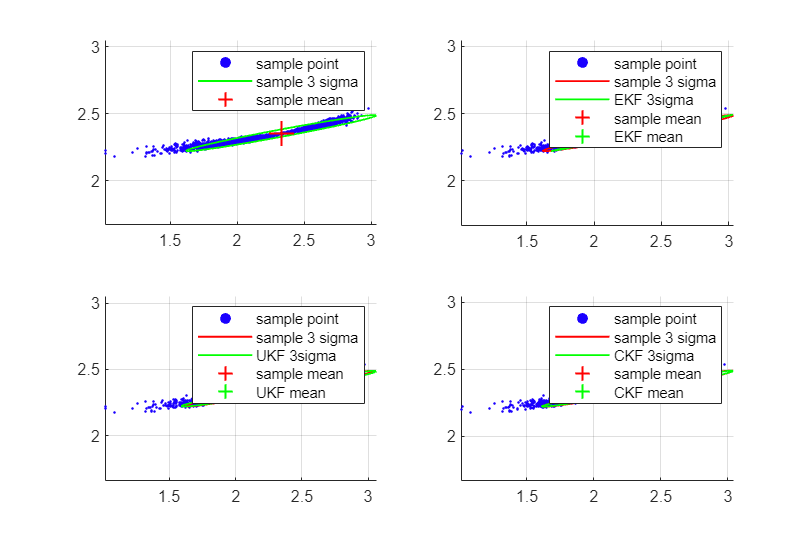

figure('Position',[300 300 600 400]);hold on;
covEllipse1 = sigmaEllipse2D(mu_y2, Sigma_y2, 3, 100);
covEllipse2 = sigmaEllipse2D(EKFmean_y2, EKFP_y2, 3, 100);
covEllipse3 = sigmaEllipse2D(UKFmean_y2, UKFP_y2, 3, 100);
covEllipse4 = sigmaEllipse2D(CKFmean_y2, CKFP_y2, 3, 100);
subplot(2,2,1)
scatter(Y2(1,:),Y2(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'-g','LineWidth',1);hold on;
plot(mu_y2(1),mu_y2(2),'+r','MarkerSize',14,'LineWidth',1)
axis equal
grid on
legend('sample point','sample 3 sigma','sample mean')
subplot(2,2,2)
scatter(Y2(1,:),Y2(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse2(1,:),covEllipse2(2,:),'-g','LineWidth',1);
plot(mu_y2(1),mu_y2(2),'+r','MarkerSize',14,'LineWidth',1)
plot(EKFmean_y2(1),EKFmean_y2(2),'+g','MarkerSize',14,'LineWidth',1)
axis equal
grid on
legend('sample point','sample 3 sigma','EKF 3sigma','sample mean','EKF mean')
subplot(2,2,3)
scatter(Y2(1,:),Y2(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse3(1,:),covEllipse3(2,:),'-g','LineWidth',1);hold on;
plot(mu_y2(1),mu_y2(2),'+r','MarkerSize',14,'LineWidth',1)
plot(UKFmean_y2(1),UKFmean_y2(2),'+g','MarkerSize',14,'LineWidth',1)
legend('sample point','sample 3 sigma','UKF 3sigma','sample mean','UKF mean')
axis equal
grid on
subplot(2,2,4)
scatter(Y2(1,:),Y2(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse4(1,:),covEllipse4(2,:),'-g','LineWidth',1);hold on;
plot(mu_y2(1),mu_y2(2),'+r','MarkerSize',14,'LineWidth',1)
plot(CKFmean_y2(1),CKFmean_y2(2),'+g','MarkerSize',14,'LineWidth',1)
legend('sample point','sample 3 sigma','CKF 3sigma','sample mean','CKF mean')
axis equal
grid on

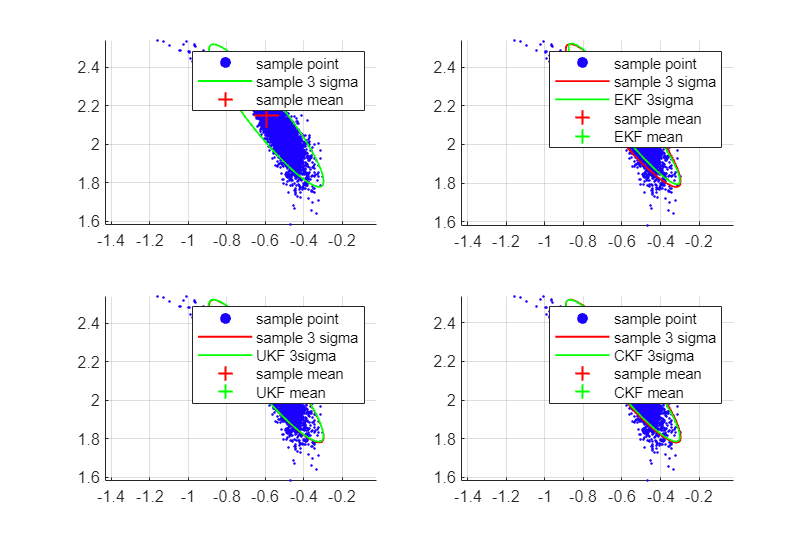

figure('Position',[300 300 600 400]);hold on;
covEllipse1 = sigmaEllipse2D(mu_y3, Sigma_y3, 3, 100);
covEllipse2 = sigmaEllipse2D(EKFmean_y3, EKFP_y3, 3, 100);
covEllipse3 = sigmaEllipse2D(UKFmean_y3, UKFP_y3, 3, 100);
covEllipse4 = sigmaEllipse2D(CKFmean_y3, CKFP_y3, 3, 100);
subplot(2,2,1)
scatter(Y3(1,:),Y3(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'-g','LineWidth',1);hold on;
plot(mu_y3(1),mu_y3(2),'+r','MarkerSize',14,'LineWidth',1)
axis equal
grid on
legend('sample point','sample 3 sigma','sample mean')
subplot(2,2,2)
scatter(Y3(1,:),Y3(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse2(1,:),covEllipse2(2,:),'-g','LineWidth',1);
plot(mu_y3(1),mu_y3(2),'+r','MarkerSize',14,'LineWidth',1)
plot(EKFmean_y3(1),EKFmean_y3(2),'+g','MarkerSize',14,'LineWidth',1)
axis equal
grid on
legend('sample point','sample 3 sigma','EKF 3sigma','sample mean','EKF mean')
subplot(2,2,3)
scatter(Y3(1,:),Y3(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse3(1,:),covEllipse3(2,:),'-g','LineWidth',1);hold on;
plot(mu_y3(1),mu_y3(2),'+r','MarkerSize',14,'LineWidth',1)
plot(UKFmean_y3(1),UKFmean_y3(2),'+g','MarkerSize',14,'LineWidth',1)
legend('sample point','sample 3 sigma','UKF 3sigma','sample mean','UKF mean')
axis equal
grid on
subplot(2,2,4)
scatter(Y3(1,:),Y3(2,:), 2,'filled', 'MarkerFaceColor',  [0.1 0 1]);hold on
plot(covEllipse1(1,:),covEllipse1(2,:),'color','red','LineWidth',1);hold on
plot(covEllipse4(1,:),covEllipse4(2,:),'-g','LineWidth',1);hold on;
plot(mu_y3(1),mu_y3(2),'+r','MarkerSize',14,'LineWidth',1)
plot(CKFmean_y3(1),CKFmean_y3(2),'+g','MarkerSize',14,'LineWidth',1)
legend('sample point','sample 3 sigma','CKF 3sigma','sample mean','CKF mean')
axis equal
grid on

# question2

clc;
clear all

T=1;s1=[-200 100]';s2=[-200 -100]';
f=@(x)coordinatedTurnMotion(x, T);
h=@(x) dualBearingMeasurement(x, s1, s2);
% Tau=[0 0 1 0 0;0 0 0 0 1]';Sigma_q=[sigma_v^2 0;0 sigma_w^2];
Tau=[0 0 1 0 0;0 0 0 0 1]';
sigma_v=1;sigma_w=pi/180;N=100

N = 100

Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau'

Q =          0         0         0         0         0
         0         0         0         0         0
         0         0    1.0000         0         0
         0         0         0         0         0
         0         0         0         0    0.0003


x_0=[0 0 20 0 5*pi/180]';
P_0=diag([10^2 10^2 2^2 (pi/180)^2 (pi/180)^2]);


# case1:

% Sigma_phi=[sigma_phi1^2 0;0 sigma_phi2^2];
sigma_phi1=2*pi/180;sigma_phi2=2*pi/180;
R1=[sigma_phi1^2 0;0 sigma_phi2^2]

R1 =     0.0012         0
         0    0.0012


X1 = genNonLinearStateSequence(x_0, P_0, f, Q, N);
Y1 = genNonLinearMeasurementSequence(X1, h, R1);
[x_EKF1, P_EKF1, ~, ~] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R1, 'EKF');
[x_UKF1, P_UKF1, ~, ~] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R1, 'UKF');
[x_CKF1, P_CKF1, ~, ~] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R1, 'CKF');
Point=[];
for i=1:N
    [x1, y1] = getPosFromMeasurement(Y1(1,i), Y1(2,i), s1, s2);
    Point=[Point;[x1, y1]];
end
Point;

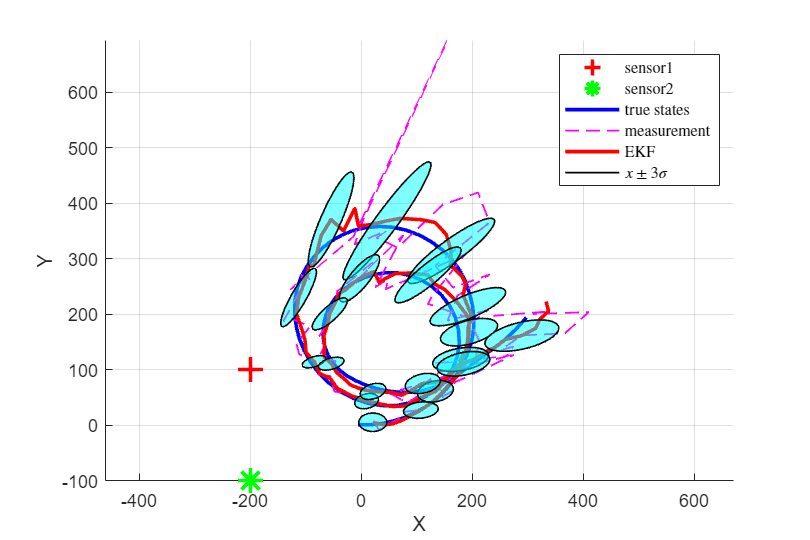

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X1(1,1:end), X1(2,1:end),'Color','blue',LineWidth=2);plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_EKF1(1,1:end), x_EKF1(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_EKF1)
    covEllipse = sigmaEllipse2D(x_EKF1(1:2,i),P_EKF1(1:2,1:2,i),3,100);
    plot(covEllipse ...
        (1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','EKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

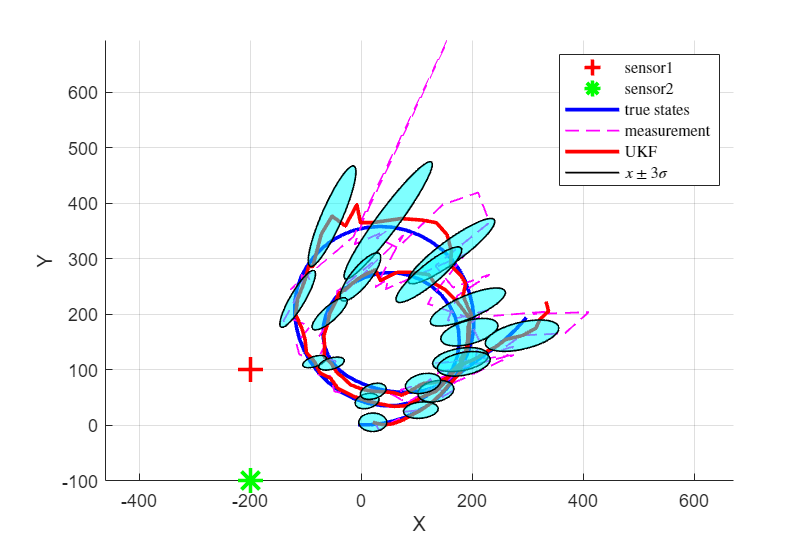

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X1(1,1:end), X1(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_UKF1(1,1:end), x_UKF1(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_EKF1)
    covEllipse = sigmaEllipse2D(x_UKF1(1:2,i),P_UKF1(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','UKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

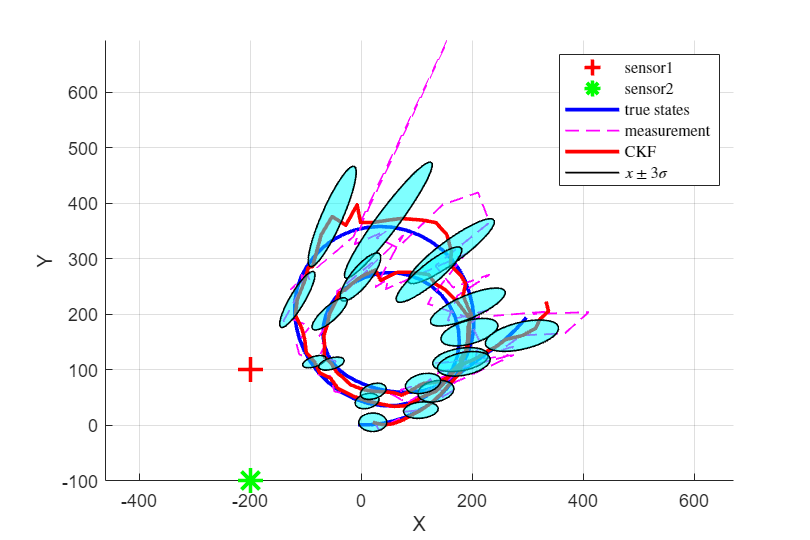

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X1(1,1:end), X1(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_CKF1(1,1:end), x_CKF1(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_CKF1)
    covEllipse = sigmaEllipse2D(x_CKF1(1:2,i),P_CKF1(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

# case2

sigma_phi1=2*pi/180;sigma_phi2=0.1*pi/180;
R2=[sigma_phi1^2 0;0 sigma_phi2^2];
X2 = genNonLinearStateSequence(x_0, P_0, f, Q, N);
Y2 = genNonLinearMeasurementSequence(X2, h, R2);
[x_EKF2, P_EKF2, ~, ~] = nonLinearKalmanFilter(Y2, x_0, P_0, f, Q, h, R2, 'EKF');
[x_UKF2, P_UKF2, ~, ~] = nonLinearKalmanFilter(Y2, x_0, P_0, f, Q, h, R2, 'UKF');
[x_CKF2, P_CKF2, ~, ~] = nonLinearKalmanFilter(Y2, x_0, P_0, f, Q, h, R2, 'CKF');
Point=[];
for i=1:N
    [x2, y2] = getPosFromMeasurement(Y2(1,i), Y2(2,i), s1, s2);
    Point=[Point;[x2, y2]];
end

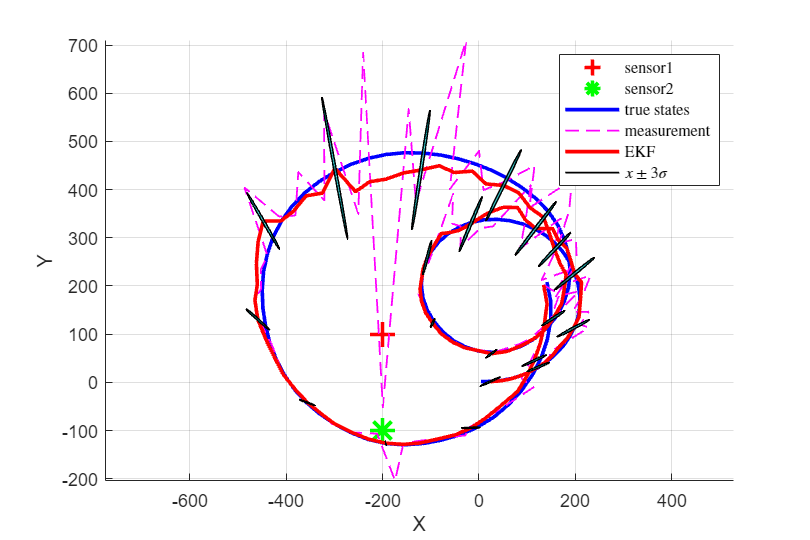

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X2(1,1:end), X2(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_EKF2(1,1:end), x_EKF2(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_EKF2)
    covEllipse = sigmaEllipse2D(x_EKF2(1:2,i),P_EKF2(1:2,1:2,i),3,100);
%     fill(ell_xy(1,:),ell_xy(2,:), '--', 'Color',cp(5,:), 'DisplayName','3-sigma level');
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','EKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

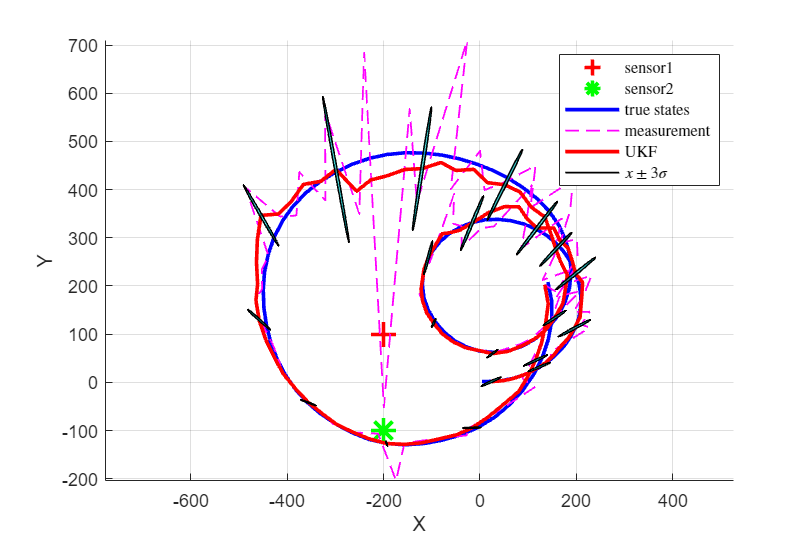

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X2(1,1:end), X2(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_UKF2(1,1:end), x_UKF2(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_UKF2)
    covEllipse = sigmaEllipse2D(x_UKF2(1:2,i),P_UKF2(1:2,1:2,i),3,100);
%     fill(ell_xy(1,:),ell_xy(2,:), '--', 'Color',cp(5,:), 'DisplayName','3-sigma level');
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','UKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

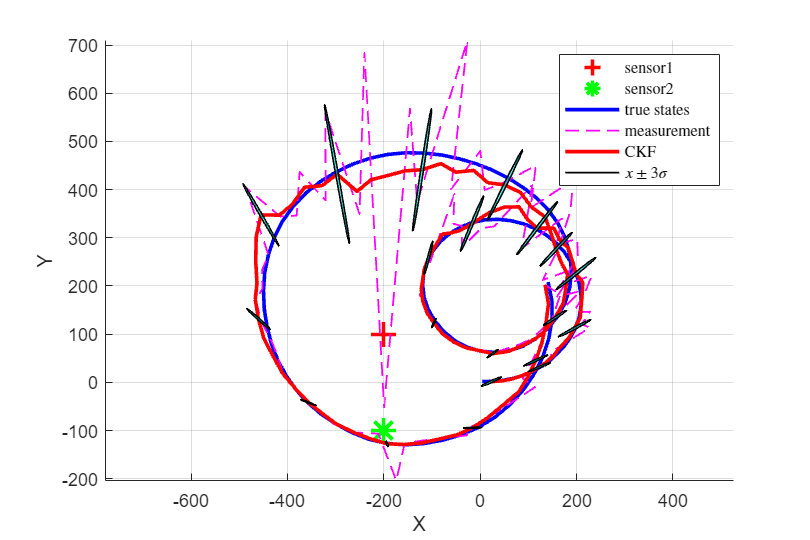

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X2(1,1:end), X2(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_CKF2(1,1:end), x_CKF2(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_UKF2)
    covEllipse = sigmaEllipse2D(x_CKF2(1:2,i),P_CKF2(1:2,1:2,i),3,100);
%     fill(ell_xy(1,:),ell_xy(2,:), '--', 'Color',cp(5,:), 'DisplayName','3-sigma level');
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

# Case3

sigma_phi1=0.1*pi/180;sigma_phi2=0.1*pi/180;
R3=[sigma_phi1^2 0;0 sigma_phi2^2];
X3 = genNonLinearStateSequence(x_0, P_0, f, Q, N);
Y3 = genNonLinearMeasurementSequence(X3, h, R3);
[x_EKF3, P_EKF3, ~, ~] = nonLinearKalmanFilter(Y3, x_0, P_0, f, Q, h, R3, 'EKF');
[x_UKF3, P_UKF3, ~, ~] = nonLinearKalmanFilter(Y3, x_0, P_0, f, Q, h, R3, 'UKF');
[x_CKF3, P_CKF3, ~, ~] = nonLinearKalmanFilter(Y3, x_0, P_0, f, Q, h, R3, 'CKF');
Point=[];
for i=1:N
    [x3, y3] = getPosFromMeasurement(Y3(1,i), Y3(2,i), s1, s2);
    Point=[Point;[x3, y3]];
end

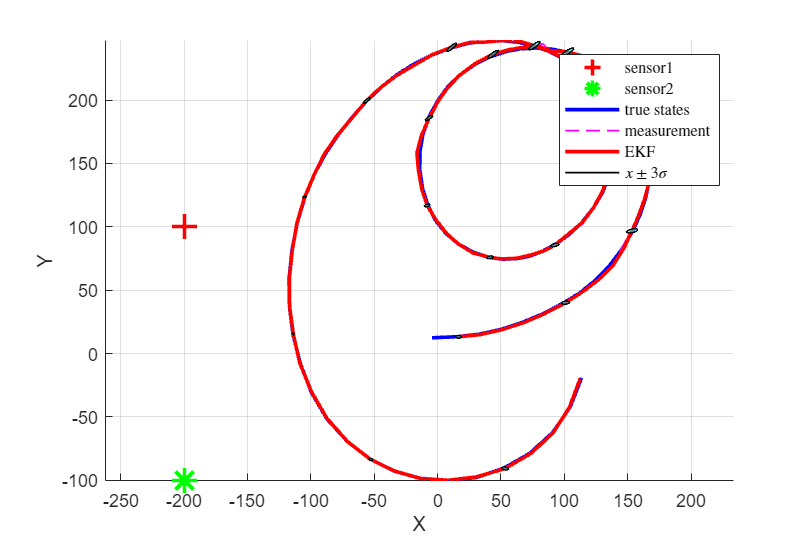

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X3(1,1:end), X3(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_EKF3(1,1:end), x_EKF3(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_EKF3)
    covEllipse = sigmaEllipse2D(x_EKF3(1:2,i),P_EKF3(1:2,1:2,i),3,100);
%     fill(ell_xy(1,:),ell_xy(2,:), '--', 'Color',cp(5,:), 'DisplayName','3-sigma level');
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','EKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

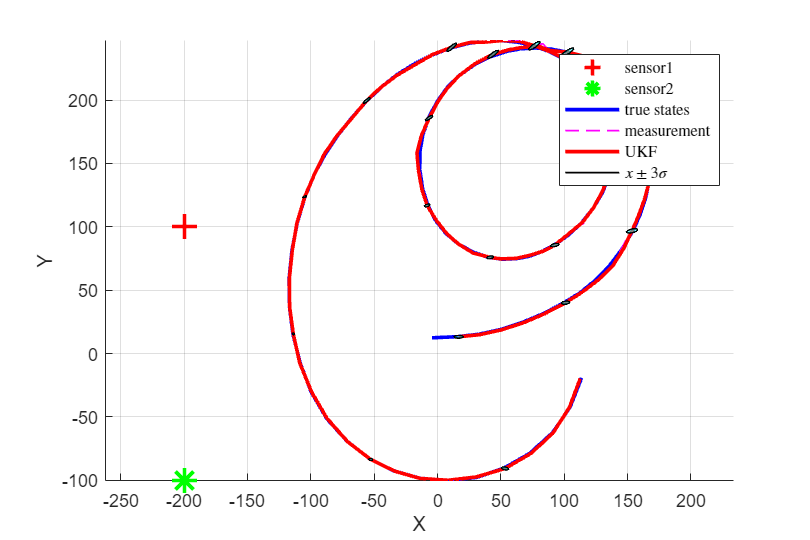

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X3(1,1:end), X3(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_UKF3(1,1:end), x_UKF3(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_UKF3)
    covEllipse = sigmaEllipse2D(x_UKF3(1:2,i),P_UKF3(1:2,1:2,i),3,100);
%     fill(ell_xy(1,:),ell_xy(2,:), '--', 'Color',cp(5,:), 'DisplayName','3-sigma level');
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','UKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

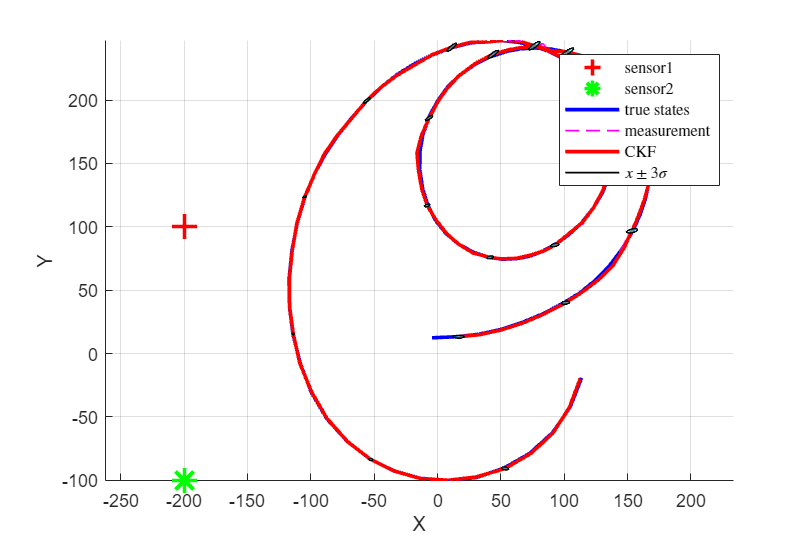

figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X3(1,1:end), X3(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(x_CKF3(1,1:end), x_CKF3(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(x_UKF3)
    covEllipse = sigmaEllipse2D(x_CKF3(1:2,i),P_CKF3(1:2,1:2,i),3,100);
%     fill(ell_xy(1,:),ell_xy(2,:), '--', 'Color',cp(5,:), 'DisplayName','3-sigma level');
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')
xlabel('X');
ylabel('Y');

# Question2(c)

MC=150;
Sigma_phi=[2*pi/180 2*pi/180;
            2*pi/180 0.1*pi/180;
            0.1*pi/180 0.1*pi/180;];
Kalman={'EKF','UKF','CKF'}

Kalman = 1×3 cell array
    {'EKF'}    {'UKF'}    {'CKF'}


error_Storage = cell(3, 3);
for casei=1:3
    sigma_phi1=Sigma_phi(casei,1);sigma_phi2=Sigma_phi(casei,2);
    R=[sigma_phi1^2 0;0 sigma_phi2^2];
    for j = 1:numel(Kalman)
        type = Kalman{j};
        error_Results = cell(1, MC);
        for imc = 1:MC
            % Simulate state sequence
            X = genNonLinearStateSequence(x_0, P_0, f, Q, N);
            % Simulate measurements
            Y = genNonLinearMeasurementSequence(X, h, R);
            % Run Kalman filter (you need to run all three, for comparison)   
            [xf,Pf,xp,Pp] = nonLinearKalmanFilter(Y,x_0,P_0,f,Q,h,R,type);
            % Save the estimation errors and the prediction errors!
            error_Results{imc} = X(1:2,2:end) - xf(1:2,:);
        end
        % Store the xf results in the corresponding cell
        error_Storage{casei, j} = error_Results;
    end
end

# % for case 1

case1  EKF   mu_x:0.84866   sigma_x:315489.063


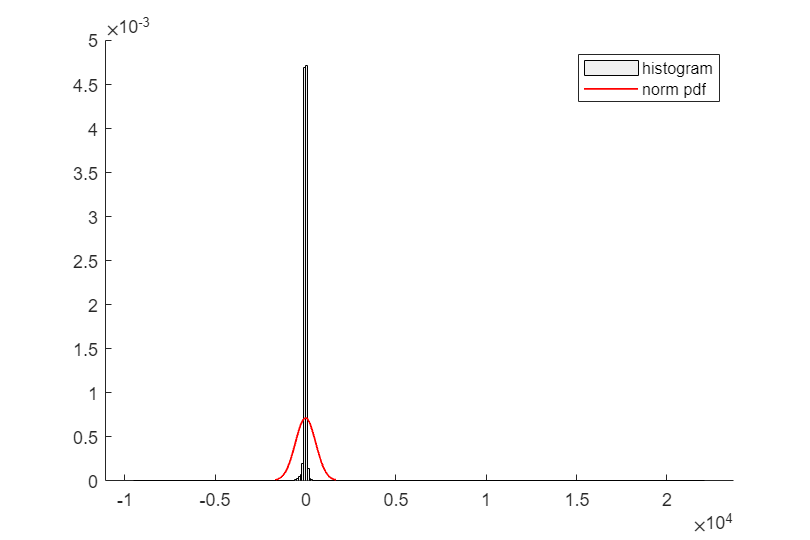

case1  EKF   mu_y:0.84866   sigma_y:315489.063


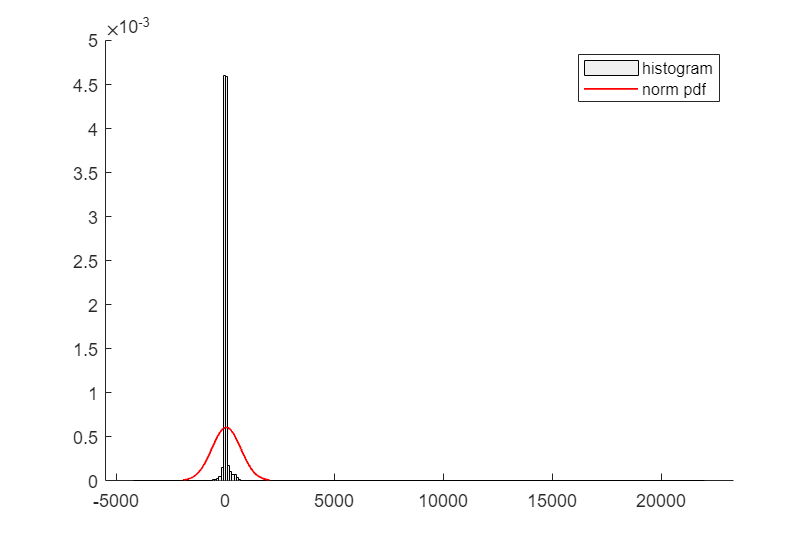

case1  UKF   mu_x:3.6753   sigma_x:1603.3969


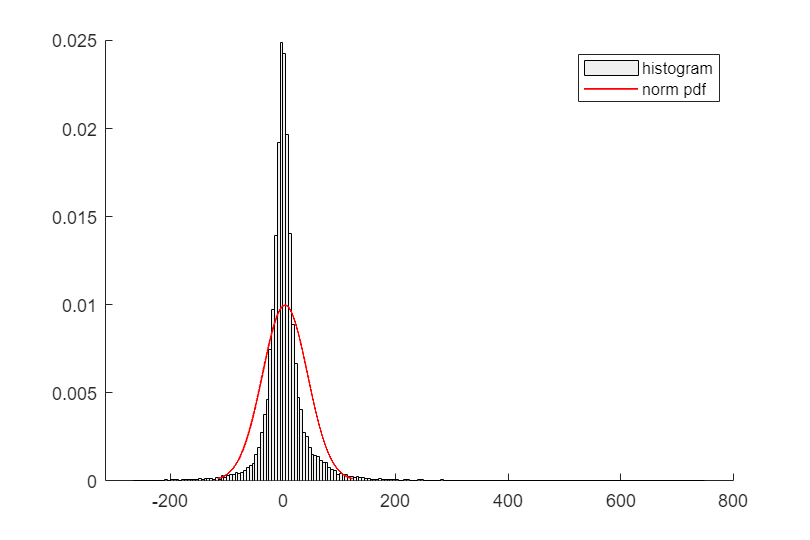

case1  UKF   mu_y:3.6753   sigma_y:1603.3969


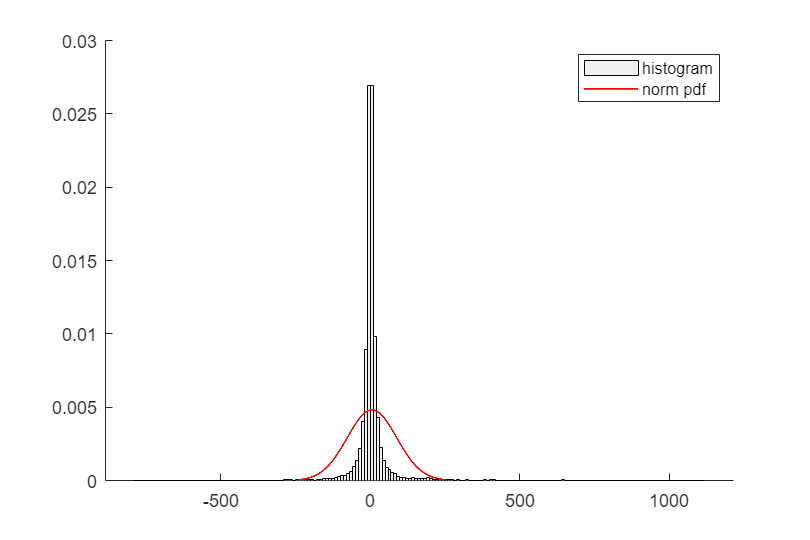

case1  CKF   mu_x:-0.43606   sigma_x:2955.8093


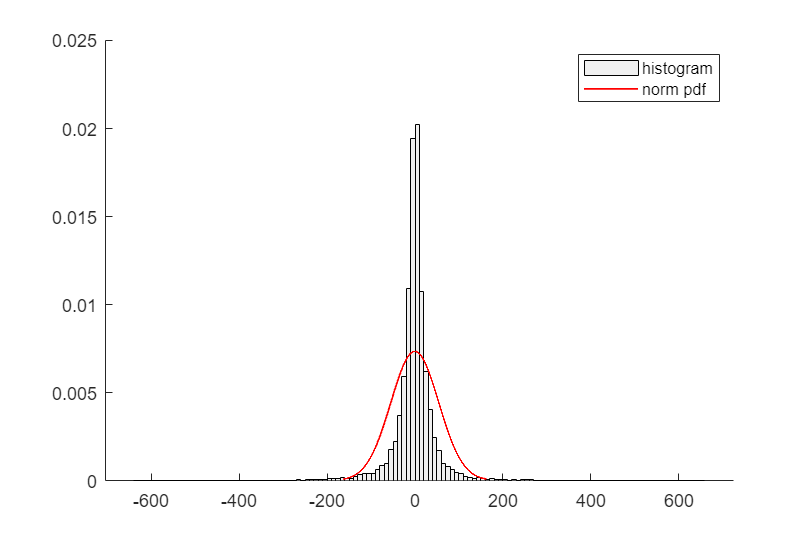

case1  CKF   mu_y:-0.43606   sigma_y:2955.8093


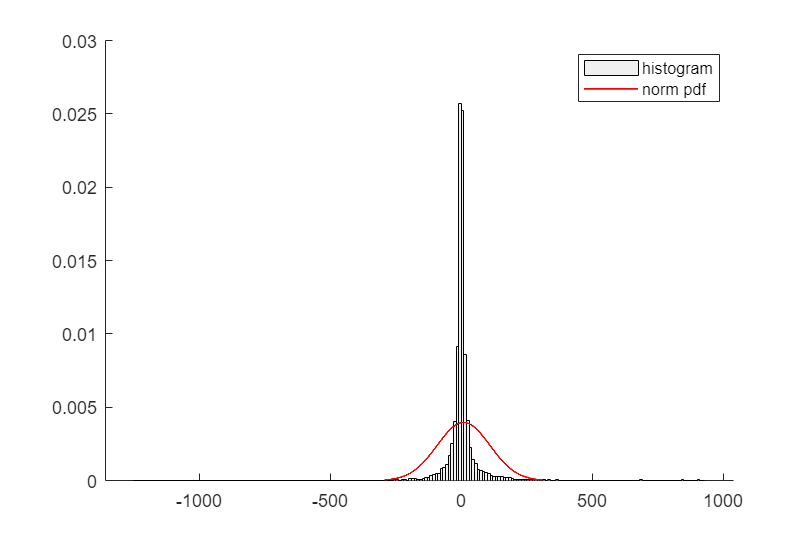

value=1;
Kalman={'EKF','UKF','CKF'};
%sequence EKF,UKF,CKF
for i=1:3
    case1=cell2mat(error_Storage{1,i});
    figure('Position',[300 300 600 400]);hold on;
    histogram(case1(1,:),'Normalization','pdf','FaceColor',[.9 .9 .9]);hold on;
    [mu_EKF1x, Sigma_EKF1x] = approxGaussianTransform(case1(1,:));
    disp(['case1  ',num2str(Kalman{i}),'   mu_x:',num2str(mu_EKF1x), '   sigma_x:',num2str(Sigma_EKF1x)])
    [x,Y]=normPlot(value,mu_EKF1x, Sigma_EKF1x);
    plot(x,Y,'LineWidth',1,'color','red');
    legend('histogram','norm pdf')
    %for y
    figure('Position',[300 300 600 400]);hold on;
    histogram(case1(2,:),'Normalization','pdf','FaceColor',[.9 .9 .9]);
    [mu_EKF1y, Sigma_EKF1y] = approxGaussianTransform(case1(2,:));
    disp(['case1  ',num2str(Kalman{i}),'   mu_y:',num2str(mu_EKF1x), '   sigma_y:',num2str(Sigma_EKF1x)])
    [x,Y]=normPlot(value,mu_EKF1y, Sigma_EKF1y);
    plot(x,Y,'LineWidth',1,'color','red');
    legend('histogram','norm pdf')
end

disp('**************')

**************


# % for case 2

case2  EKF   mu_x:-324.7522   sigma_x:28228331.7198


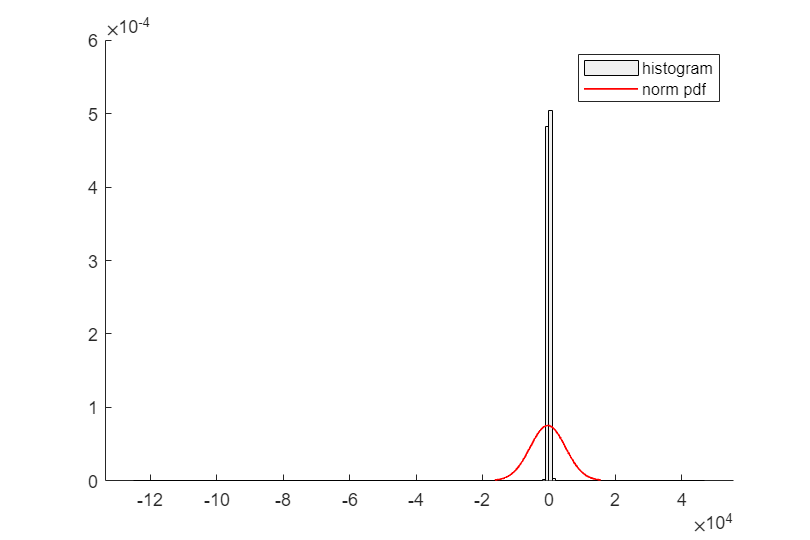

case2  EKF   mu_y:-324.7522   sigma_y:28228331.7198


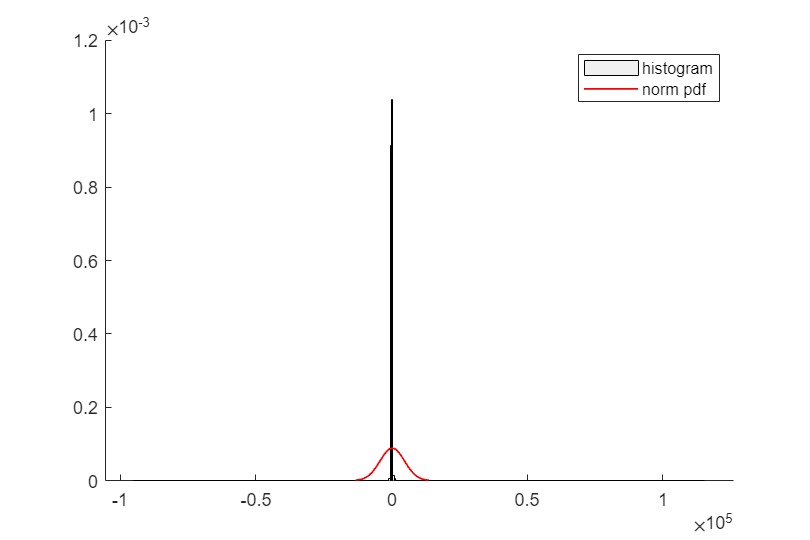

case2  UKF   mu_x:1.0272   sigma_x:2497.5381


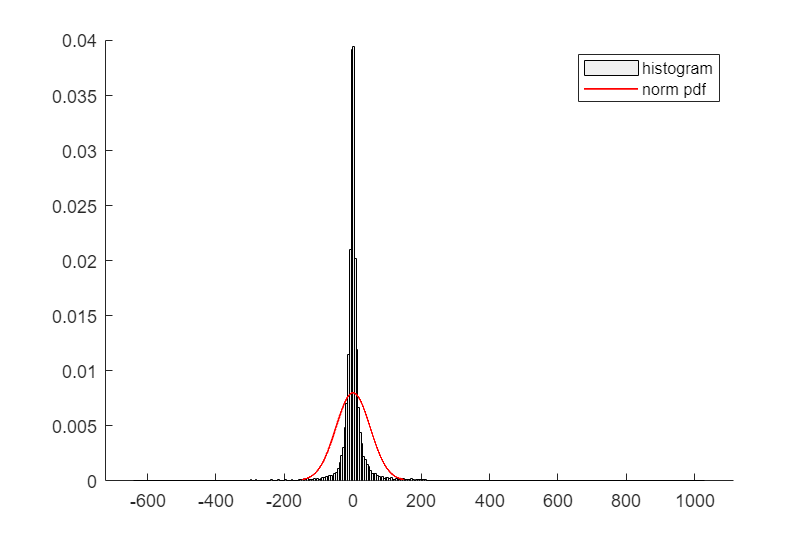

case2  UKF   mu_y:1.0272   sigma_y:2497.5381


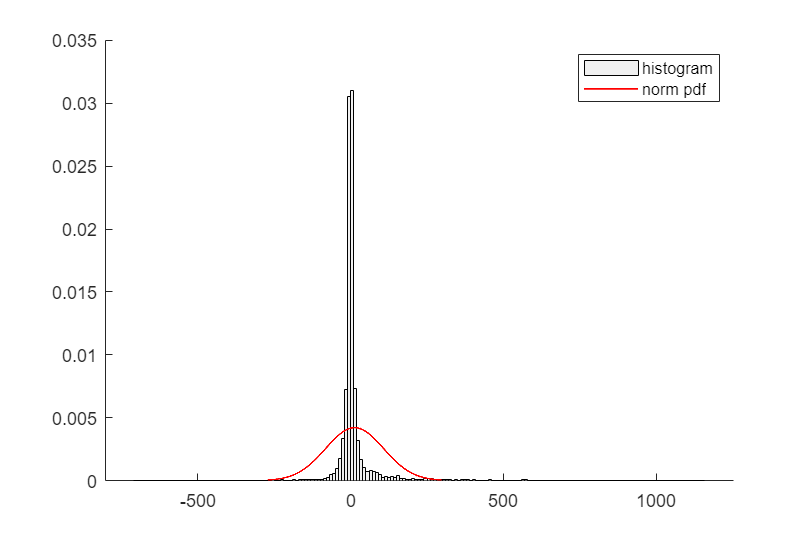

case2  CKF   mu_x:-2.9226   sigma_x:8898851.5674


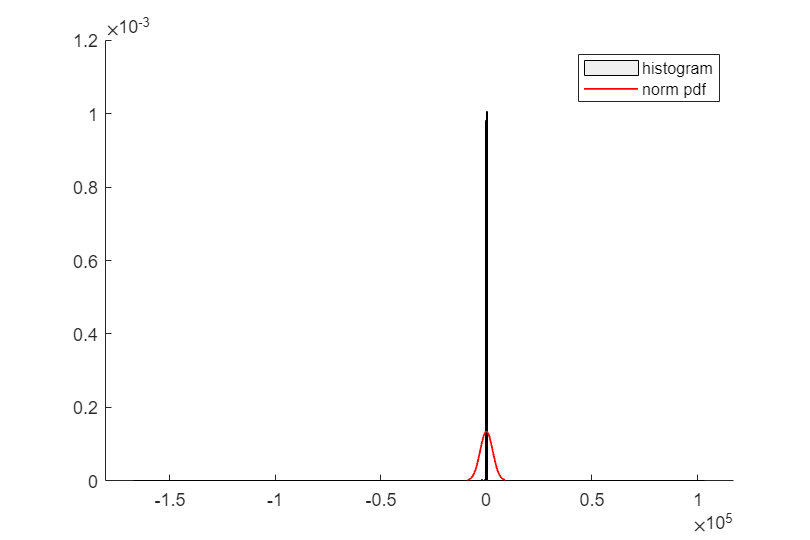

case2  CKF   mu_y:-2.9226   sigma_y:8898851.5674


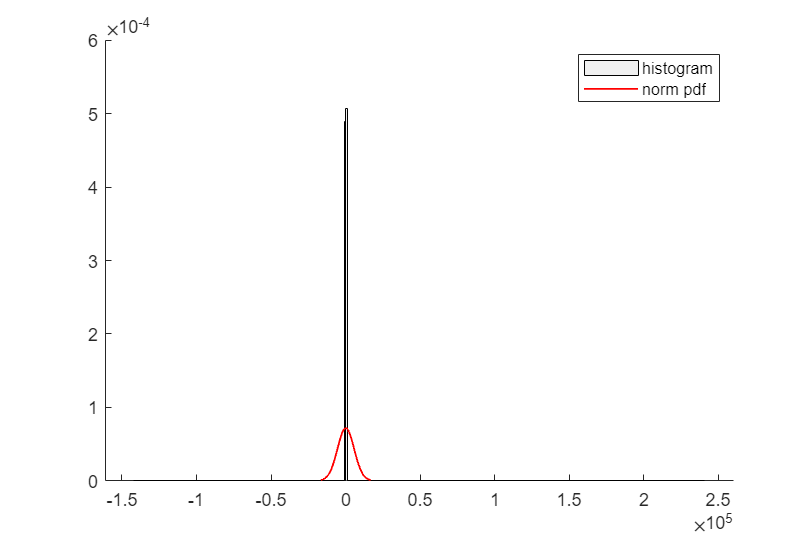

value=1;
Kalman={'EKF','UKF','CKF'};
%sequence EKF,UKF,CKF
for i=1:3
    case1=cell2mat(error_Storage{2,i});
    figure('Position',[300 300 600 400]);hold on;
    histogram(case1(1,:),'Normalization','pdf','FaceColor',[.9 .9 .9]);hold on;
    [mu_EKF1x, Sigma_EKF1x] = approxGaussianTransform(case1(1,:));
    disp(['case2  ',num2str(Kalman{i}),'   mu_x:',num2str(mu_EKF1x), '   sigma_x:',num2str(Sigma_EKF1x)])
    [x,Y]=normPlot(value,mu_EKF1x, Sigma_EKF1x);
    plot(x,Y,'LineWidth',1,'color','red');
    legend('histogram','norm pdf')
    %for y
    figure('Position',[300 300 600 400]);hold on;
    histogram(case1(2,:),'Normalization','pdf','FaceColor',[.9 .9 .9]);
    [mu_EKF1y, Sigma_EKF1y] = approxGaussianTransform(case1(2,:));
    disp(['case2  ',num2str(Kalman{i}),'   mu_y:',num2str(mu_EKF1x), '   sigma_y:',num2str(Sigma_EKF1x)])
    [x,Y]=normPlot(value,mu_EKF1y, Sigma_EKF1y);
    plot(x,Y,'LineWidth',1,'color','red');
    legend('histogram','norm pdf')
end

disp('**************')

**************


# % for case 3

case3  EKF   mu_x:-0.090243   sigma_x:25.1282


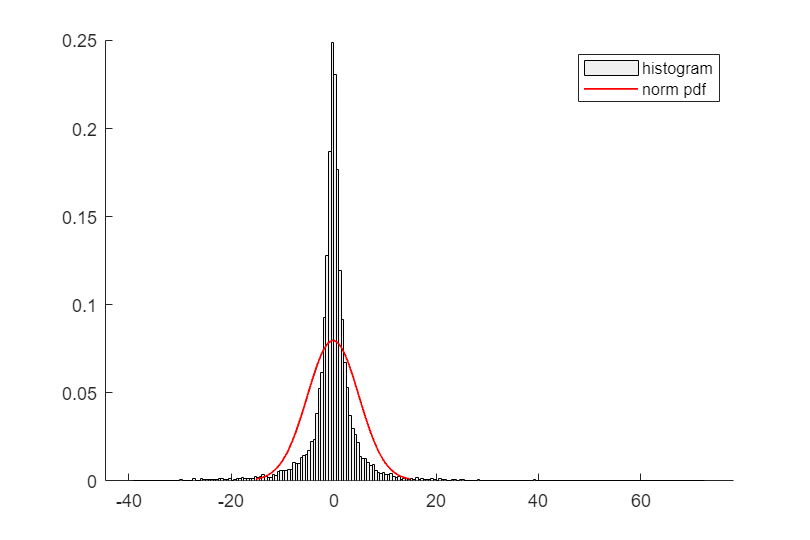

case3  EKF   mu_y:-0.090243   sigma_y:25.1282


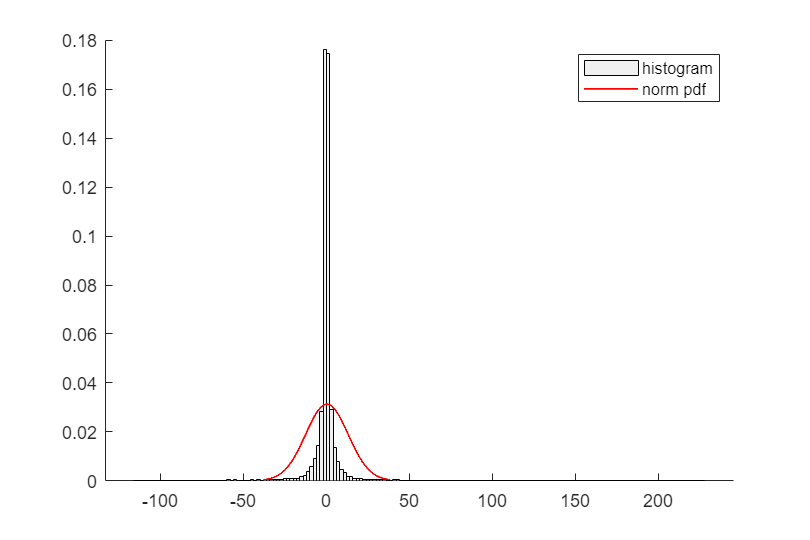

case3  UKF   mu_x:0.060546   sigma_x:24.674


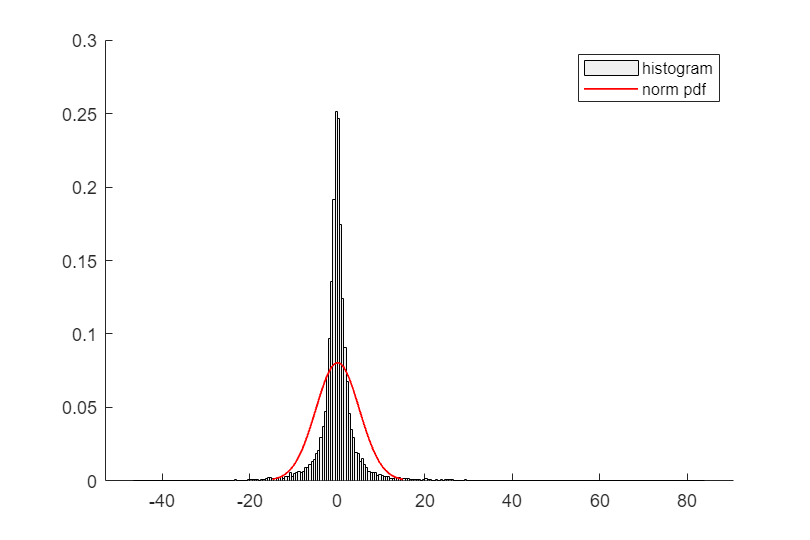

case3  UKF   mu_y:0.060546   sigma_y:24.674


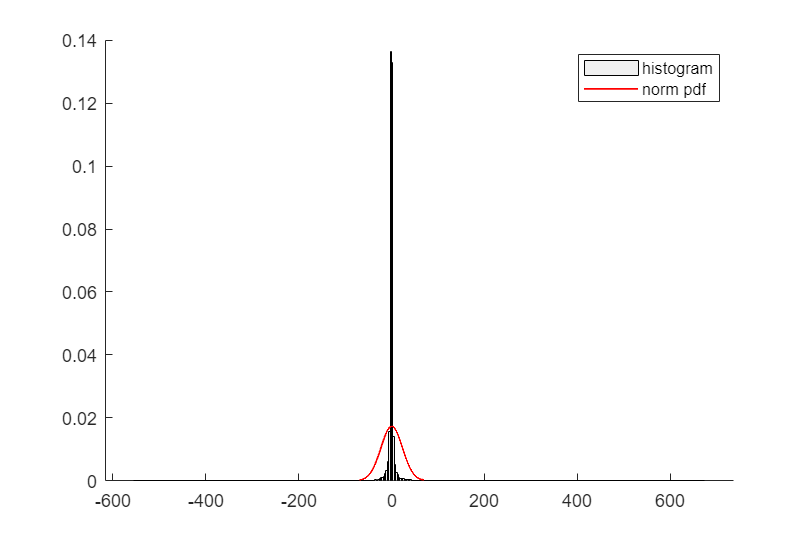

case3  CKF   mu_x:-0.048676   sigma_x:24.4192


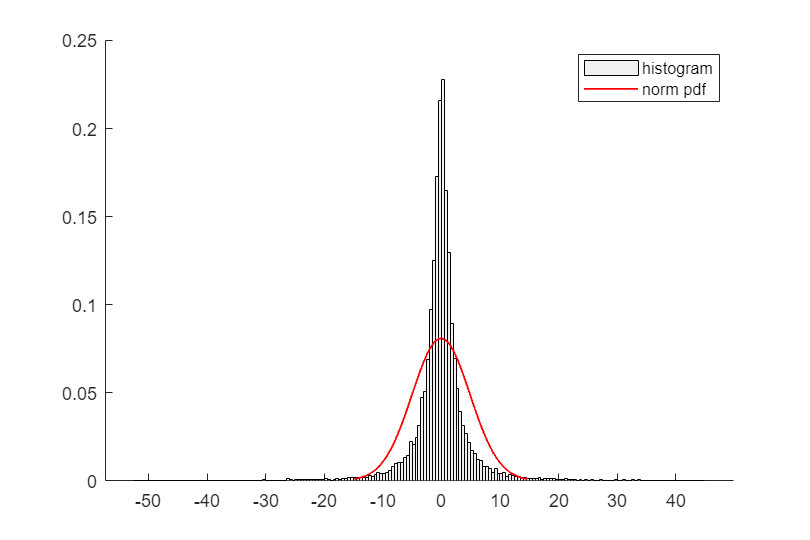

case3  CKF   mu_y:-0.048676   sigma_y:24.4192


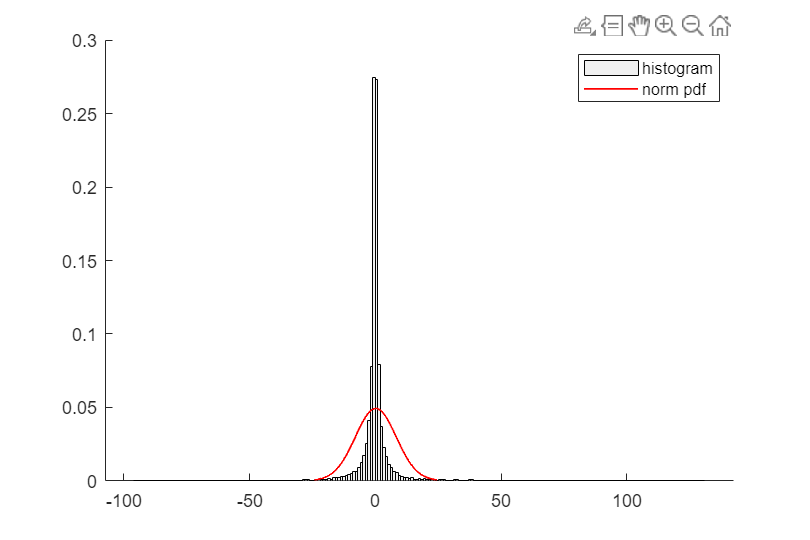

value=1;
Kalman={'EKF','UKF','CKF'};
%sequence EKF,UKF,CKF
for i=1:3
    case1=cell2mat(error_Storage{3,i});
    figure('Position',[300 300 600 400]);hold on;
    histogram(case1(1,:),'Normalization','pdf','FaceColor',[.9 .9 .9]);hold on;
    [mu_EKF1x, Sigma_EKF1x] = approxGaussianTransform(case1(1,:));
    disp(['case3  ',num2str(Kalman{i}),'   mu_x:',num2str(mu_EKF1x), '   sigma_x:',num2str(Sigma_EKF1x)])
    [x,Y]=normPlot(value,mu_EKF1x, Sigma_EKF1x);
    plot(x,Y,'LineWidth',1,'color','red');
    legend('histogram','norm pdf')
    %for y
    figure('Position',[300 300 600 400]);hold on;
    histogram(case1(2,:),'Normalization','pdf','FaceColor',[.9 .9 .9]);
    [mu_EKF1y, Sigma_EKF1y] = approxGaussianTransform(case1(2,:));
    disp(['case3  ',num2str(Kalman{i}),'   mu_y:',num2str(mu_EKF1x), '   sigma_y:',num2str(Sigma_EKF1x)])
    [x,Y]=normPlot(value,mu_EKF1y, Sigma_EKF1y);
    plot(x,Y,'LineWidth',1,'color','red');
    legend('histogram','norm pdf')
end

disp('**************')

**************


# question3

clear all
clc
%% True track
% Sampling period
T = 0.1;
% Length of time sequence
K = 600;
% Allocate memory
omega = zeros(1,K+1);
% Turn rate
omega(150:450) = -pi/301/T;
% Initial state
x0 = [0 0 20 0 omega(1)]';
% Allocate memory
X = zeros(length(x0),K+1);
X(:,1) = x0;
% Create true track
for i=2:K+1
    % Simulate
    X(:,i) = coordinatedTurnMotion(X(:,i-1), T);
    % Set turn−rate
    X(5,i) = omega(i);
end
x_0=[0 0 0 0 0]';N=length(X);
P_0=diag([10^2 10^2 10^2 (5*pi/180)^2 (pi/180)^2]);
s1=[300 -100]';s2=[300 -300]';
sigma_phi1=pi/180;sigma_phi2=pi/180;
R=[sigma_phi1^2 0;0 sigma_phi2^2];
Tau=[0 0 1 0 0;0 0 0 0 1]';
f=@(x)coordinatedTurnMotion(x, T);
h=@(x) dualBearingMeasurement(x, s1, s2);
Y1 = genNonLinearMeasurementSequence(X, h, R);
Point=[];
for i=1:600
    [x1, y1] = getPosFromMeasurement(Y1(1,i), Y1(2,i), s1, s2);
    Point=[Point;[x1, y1]];
end
Point;

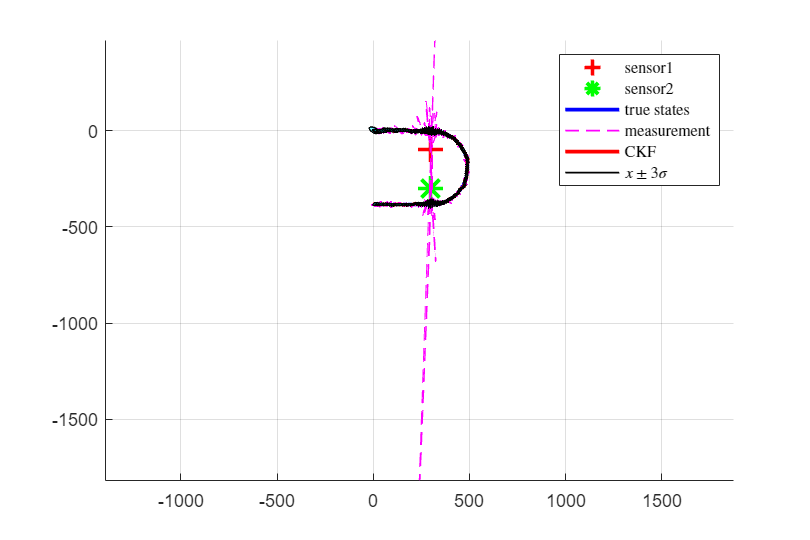

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%decrease 1
sigma_v=0.1;sigma_w=pi/180;
Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau';
[xf_tunning, Pf, xp, Pp] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R, 'CKF');
figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xf_tunning(1,1:end), xf_tunning(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xf_tunning)
    covEllipse = sigmaEllipse2D(xf_tunning(1:2,i),Pf(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')

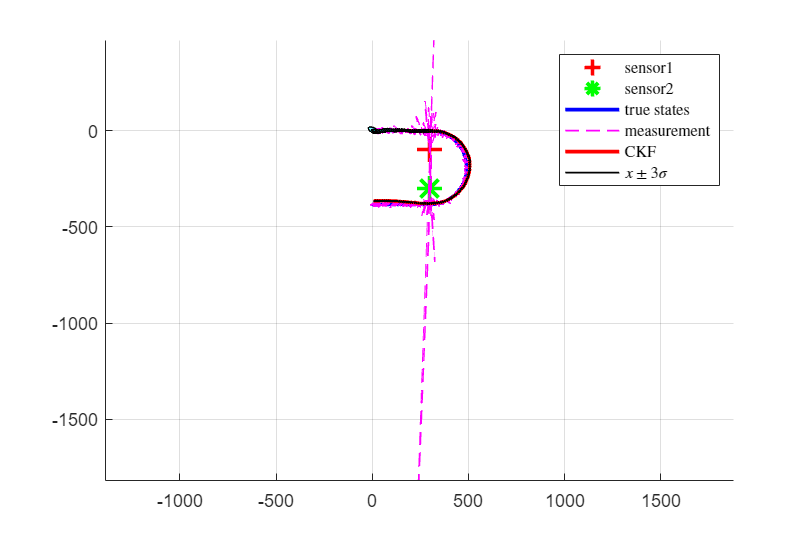

%decrease both
sigma_v=0.01;sigma_w=0.01*pi/180;
Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau';
[xf_small, Pf, xp, Pp] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R, 'CKF');
figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xf_small(1,1:end), xf_small(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xf_small)
    covEllipse = sigmaEllipse2D(xf_small(1:2,i),Pf(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')

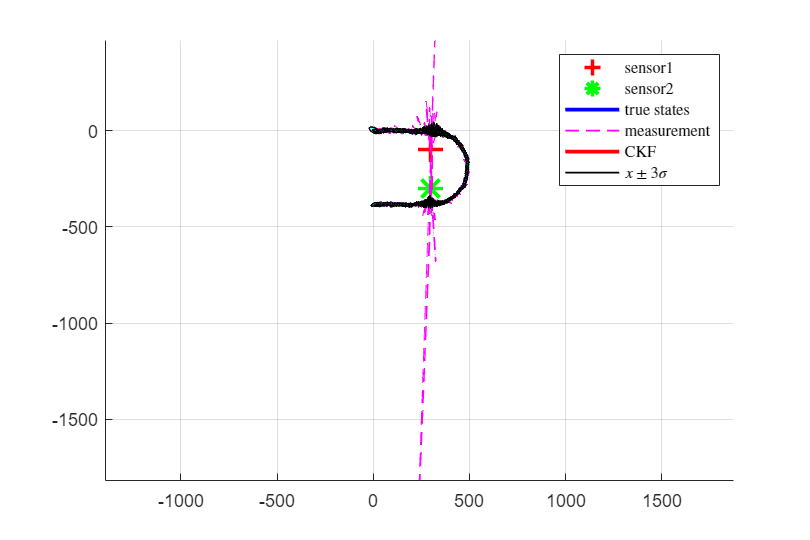

%no change
sigma_v=1;sigma_w=pi/180;
Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau';
[xf, Pf, xp, Pp] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R, 'CKF');
figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xf(1,1:end), xf(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xf)
    covEllipse = sigmaEllipse2D(xf(1:2,i),Pf(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')

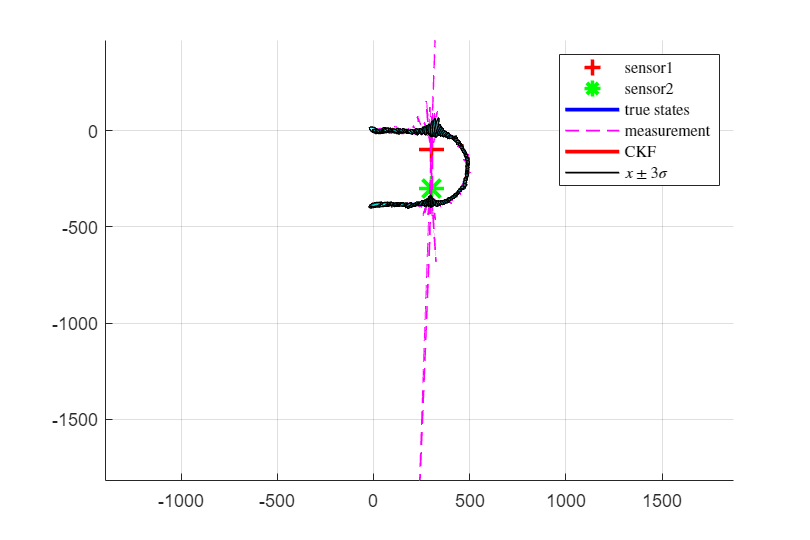

%increasing 1
sigma_v=100;sigma_w=pi/180;
Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau';
[xf, Pf, xp, Pp] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R, 'CKF');
figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xf(1,1:end), xf(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xf)
    covEllipse = sigmaEllipse2D(xf(1:2,i),Pf(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')

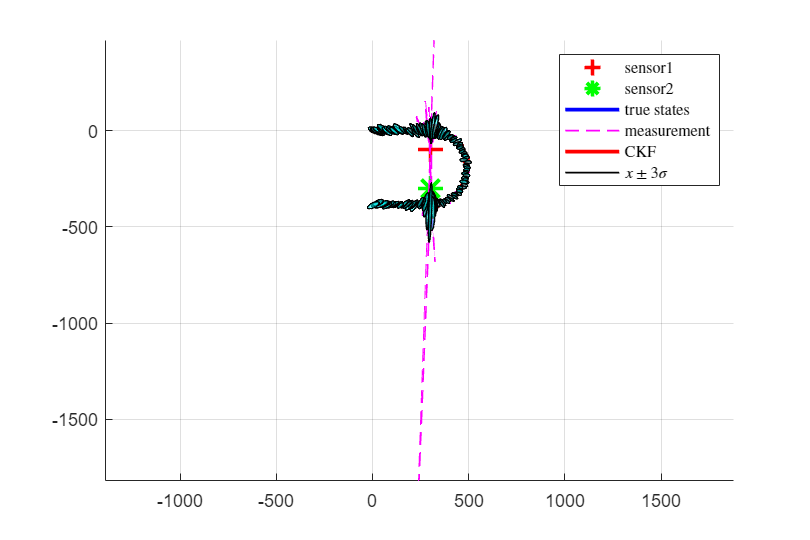

%too large
sigma_v=100;sigma_w=100*pi/180;
Q=Tau*[sigma_v^2 0;0 sigma_w^2]*Tau';
[xf_large, Pf, xp, Pp] = nonLinearKalmanFilter(Y1, x_0, P_0, f, Q, h, R, 'CKF');
figure('Position',[300 300 600 400]);hold on;
plot(s1(1),s1(2),'+r','MarkerSize',14,'LineWidth',2);
plot(s2(1),s2(2),'*g','MarkerSize',14,'LineWidth',2);
plot(X(1,1:end), X(2,1:end),'Color','blue',LineWidth=2);
plot(Point(1:end,1), Point(1:end,2),'--k','Color','m',LineWidth=1);
plot(xf_large(1,1:end), xf_large(2,1:end),'Color','r',LineWidth=2);
for i=1:5:length(xf_large)
    covEllipse = sigmaEllipse2D(xf_large(1:2,i),Pf(1:2,1:2,i),3,100);
    plot(covEllipse(1,:),covEllipse(2,:),'black','LineWidth',1);
    fill(covEllipse(1,:),covEllipse(2,:), 'cyan','FaceAlpha', 0.5);
end
axis equal
grid on
legend('sensor1', 'sensor2','true states','measurement','CKF','$x \pm 3\sigma$','Interpreter','latex')

Norm_tunning=vecnorm(X(1:2,2:end)-xf_tunning(1:2,:))

Norm_tunning =     3.5034    2.9038    6.3825    7.0344    6.1702    5.8412    2.4924    4.7136    2.3265    2.5762    2.3164    2.9331    3.9558    3.1105    3.6473    3.6866    4.7309    4.3674    3.8417    3.6601    4.2265    5.3224    5.0917    4.6657    5.3504    5.1427    3.7623    5.3934    4.9010    5.6911    5.2842    3.2884    5.6583    7.3170    7.3377    9.1774   11.2069    9.3411   10.3346   10.5962    8.7858    9.6998    8.2387    9.3359    9.8148    9.9187   11.4073    9.5092   11.1591    8.7783


Norm_large=vecnorm(X(1:2,2:end)-xf_large(1:2,:))

Norm_large =     3.5034    1.7567   11.8249    9.7272   14.0330   12.0626    3.4015   10.5906    2.4699    4.0882    3.1781    6.5761    7.1483    5.5354    7.2719    4.9649    4.6968    5.6091    9.7134    6.0025   10.2345   16.2430   11.4709    4.3423    7.2006    3.6895    6.8824   16.9608   12.4098   13.5194    5.6039    8.0231    5.7739   10.7824   13.6822   19.6581   27.2246    2.1601   14.8124   12.0209    6.8521   10.1008    2.2603    9.6354    4.6938    5.0427   12.0077    7.0130   14.6769    7.0676


Norm_small=vecnorm(X(1:2,2:end)-xf_small(1:2,:))

Norm_small =     3.5034    2.9038    6.3825    7.0343    6.1701    5.8409    2.4924    4.7133    2.3266    2.5763    2.3170    2.9336    3.9571    3.1100    3.6455    3.6854    4.7244    4.3517    3.8761    3.6727    4.2173    5.2619    4.9558    4.5844    5.2850    4.9783    3.4989    4.8147    4.1985    4.7731    4.2031    2.4688    4.0538    5.1686    4.5637    6.1284    7.7854    6.1702    7.4957    8.0216    7.0735    7.8188    6.4746    7.8712    8.0892    8.3615    9.5941    8.7380    9.2775    8.1711


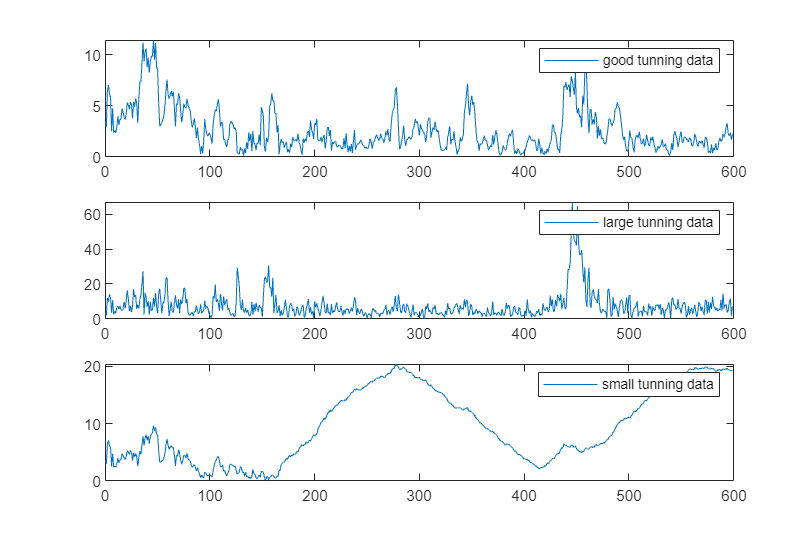

figure('Position',[300 300 600 400]);hold on;
subplot(3,1,1)
plot(0:599,Norm_tunning)
legend("good tunning data")
subplot(3,1,2)
plot(0:599,Norm_large)
legend("large tunning data")
subplot(3,1,3)
plot(0:599,Norm_small)
legend("small tunning data")

# Getposition Function

function [x, y] = getPosFromMeasurement(y1, y2, s1, s2)
%GETPOSFROMMEASUREMENT computes the intersection point
%(transformed 2D measurement in Cartesian coordinate
%system) given two sensor locations and two bearing
%measurements, one from each sensor.
%INPUT: y1: bearing measurement from sensor 1
% y2: bearing measurement from sensor 2
% s1: location of sensor 1 in 2D Cartesian
% s2: location of sensor 2 in 2D Cartesian
%OUTPUT: x: coordinate of intersection point on x axis
% y: coordinate of intersection point on y axis
%This problem can be formulated as solving a set of two
%linear equations with two unknowns. Specifically, one
%would like to obtain (x,y) by solving
%(y−s1(2))=(x−s1(1))tan(y1) and (y−s2(2))=(x−s2(1))tan(y2).
x = (s2(2)-s1(2)+tan(y1)*s1(1)-tan(y2)*s2(1))/(tan(y1)-tan(y2));
y = s1(2)+tan(y1)*(x-s1(1));
end

# sigmaEllipse2D

function [ xy ] = sigmaEllipse2D( mu, Sigma, level, nPoints )
%SIGMAELLIPSE2D generates x,y-points which lie on the ellipse describing
% a sigma level in the Gaussian density defined by mean and covariance.
%
%Input:
%   MU          [2 x 1] Mean of the Gaussian density
%   SIGMA       [2 x 2] Covariance matrix of the Gaussian density
%   LEVEL       Which sigma level curve to plot. Default = 3.
%   NPOINTS     Number of points on the ellipse to generate. Default = 32.
%
%Output:
%   XY          2 x npoints matrix. First row holds x-coordinates, second
%               row holds the y-coordinates.

if nargin < 3
    level = 3;
end
if nargin < 4
    nPoints = 32;
end

th = linspace(0,2*pi,nPoints);
xy = mu + level*sqrtm(Sigma)*[cos(th); sin(th)];

end

# normPlot function

function [x,Y]=normPlot(value,mu,variance)
%GENLINEARSTATESEQUENCE generates an N-long sequence of states using a 
%    Gaussian prior and a linear Gaussian process model
%
%Input:
%   mu         mean
%   X_true     true value of X
%   X_estimate          estimate value from kalman filter
%   variance=(X_true(:,k+1)-X_estimate(:,k))^2;
%   k           sample time
%   value       domain 
%
%Output:
%   Y           normpdf of Y
value=3*sqrt(variance);
x=[mu-value:0.1:mu+value];
Y=normpdf(x,mu,sqrt(variance));
end

# approxGaussian function

function [mu_y, Sigma_y] = approxGaussianTransform(data)
N=length(data);
mu_y=mean(data,2);
Sigma_y=(data-mu_y)*(data-mu_y)'/(N-1);
end

# Functions for nonlinear kalman

# HA3.1.1 Coordinated turn motion model

function [fx, Fx] = coordinatedTurnMotion(x, T)
%COORDINATEDTURNMOTION calculates the predicted state using a coordinated
%turn motion model, and also calculated the motion model Jacobian
%
%Input:
%   x           [5 x 1] state vector
%   T           [1 x 1] Sampling time
%
%Output:
%   fx          [5 x 1] motion model evaluated at state x
%   Fx          [5 x 5] motion model Jacobian evaluated at state x
%
% NOTE: the motion model assumes that the state vector x consist of the
% following states:
%   px          X-position
%   py          Y-position
%   v           velocity
%   phi         heading
%   omega       turn-rate

% Your code for the motion model here
fx =[x(1)+T*x(3)*cos(x(4));x(2)+T*x(3)*sin(x(4));x(3);x(4)+T*x(5);x(5)];

%Check if the Jacobian is requested by the calling function
if nargout > 1
    % Your code for the motion model Jacobian here
    % Fx = ...
    Fx=eye(5);
    Fx(1:2,3:4)=[T*cos(x(4)) -T*x(3)*sin(x(4));T*sin(x(4)) T*x(3)*cos(x(4))];
    Fx(4,5)=T;
end

end


# HA3.1.2 Dual Bearing Measurement Model


function [hx, Hx] = dualBearingMeasurement(x, s1, s2)
%DUOBEARINGMEASUREMENT calculates the bearings from two sensors, located in 
%s1 and s2, to the position given by the state vector x. Also returns the
%Jacobian of the model at x.
%
%Input:
%   x           [n x 1] State vector, the two first element are 2D position
%   s1          [2 x 1] Sensor position (2D) for sensor 1
%   s2          [2 x 1] Sensor position (2D) for sensor 2
%
%Output:
%   hx          [2 x 1] measurement vector
%   Hx          [2 x n] measurement model Jacobian
%
% NOTE: the measurement model assumes that in the state vector x, the first
% two states are X-position and Y-position.

% Your code here
n=size(x,1);
y1=x(2,:)-s1(2);
y2=x(2,:)-s2(2);
x1=x(1,:)-s1(1);
x2=x(1,:)-s2(1);
hx=[atan2(y1,x1);
    atan2(y2,x2)];
    
Hx =[-y1/(x1^2+y1^2),x1/(x1^2+y1^2),zeros(1,n-2);
    -y2/(x2^2+y2^2),x2/(x2^2+y2^2),zeros(1,n-2)];
end


# HA3.1.3 Generate non-linear state sequence

function X = genNonLinearStateSequence(x_0, P_0, f, Q, N)
%GENNONLINEARSTATESEQUENCE generates an N+1-long sequence of states using a 
%    Gaussian prior and a nonlinear Gaussian process model
%
%Input:
%   x_0         [n x 1] Prior mean
%   P_0         [n x n] Prior covariance
%   f           Motion model function handle
%               [fx,Fx]=f(x) 
%               Takes as input x (state), 
%               Returns fx and Fx, motion model and Jacobian evaluated at x
%               All other model parameters, such as sample time T,
%               must be included in the function
%   Q           [n x n] Process noise covariance
%   N           [1 x 1] Number of states to generate
%
%Output:
%   X           [n x N+1] State vector sequence
%

% Your code here
X0= mvnrnd(x_0, P_0)';
X=X0;
% fx=f(:,1)
% Fx=f(:,2:end)
for i=1:N
    q=mvnrnd(zeros(length(x_0),1), Q)';
    X=[X f(X(:,i))+q];
end

end


# HA3.1.4 Generate non-linear measurements

function Y = genNonLinearMeasurementSequence(X, h, R)
%GENNONLINEARMEASUREMENTSEQUENCE generates ovservations of the states 
% sequence X using a non-linear measurement model.
%
%Input:
%   X           [n x N+1] State vector sequence
%   h           Measurement model function handle
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state) 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   Y           [m x N] Measurement sequence
%

% Your code here
Y=[];
for i=2:length(X)
    Y=[Y, h(X(:,i))+mvnrnd(zeros(length(R),1),R)'];
end
end


# HA3.1.5 Compute sigma points

function [SP,W] = sigmaPoints(x, P, type)
% SIGMAPOINTS computes sigma points, either using unscented transform or
% using cubature.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%
%Output:
%   SP          [n x 2n+1] UKF, [n x 2n] CKF. Matrix with sigma points
%   W           [1 x 2n+1] UKF, [1 x 2n] UKF. Vector with sigma point weights 
%
n=length(x);
sqrtP=sqrtm(P);
    switch type        
        case 'UKF'
        SP=zeros(n,2*n+1);
        W=zeros(1,2*n+1);
        W(:,1)=1-n/3;
        SP(:,1)=x;
        for i=1:n
            W(:,i+1)=(1-W(:,1))/(2*n);
            W(:,n+i+1)=(1-W(:,1))/(2*n);
            SP(:,i+1)=x+sqrt(n/(1-W(:,1)))*sqrtP(:,i);
            SP(:,i+n+1)=x-sqrt(n/(1-W(:,1)))*sqrtP(:,i);
        end
            % your code     
        case 'CKF'
        SP=zeros(n,2*n);
        W=zeros(1,2*n);  
            % your code
        for i=1:n
            W(:,i)=1/(2*n);
            W(:,i+n)=1/(2*n);
            SP(:, i) = x+sqrt(n)*sqrtP(:,i);
            SP(:, i+n) = x-sqrt(n)*sqrtP(:,i);
        end
        otherwise
            error('Incorrect type of sigma point')
    end

end


# HA3.1.6 Non-linear Kalman prediction

function [x, P] = nonLinKFprediction(x, P, f, Q, type)
%NONLINKFPREDICTION calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   f           Motion model function handle
%               [fx,Fx]=f(x) 
%               Takes as input x (state), 
%               Returns fx and Fx, motion model and Jacobian evaluated at x
%               All other model parameters, such as sample time T,
%               must be included in the function
%   Q           [n x n] Process noise covariance
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] predicted state mean
%   P           [n x n] predicted state covariance
n=length(x);

    switch type
        case 'EKF'
           [fx,Fx]=f(x);
            x_before=x;
            P_before=P;
            % Your EKF code here
            x=fx;
            P=Fx*P_before*Fx'+Q;   
        case 'UKF'
            % Your UKF code here
            [SP,W] = sigmaPoints(x, P, 'UKF');
%             [fx,Fx]=f(SP);
            x=zeros(n,1);P=zeros(n,n);
            f_pred = zeros(n, length(W));
            for i=1:length(W)
                f_pred(:,i) = f(SP(:,i));
                x=x+f_pred(:,i)*W(i);
            end
            for i=1:length(W)
                P=P+(f_pred(:,i)-x)*(f_pred(:,i)-x)'*W(i);
            end
             P=P+Q;
            % Make sure the covariance matrix is semi-definite
            if min(eig(P))<=0
                [v,e] = eig(P, 'vector');
                e(e<0) = 1e-4;
                P = v*diag(e)/v;
            end
                
        case 'CKF'
            
            % Your CKF code here
            [SP,W] = sigmaPoints(x, P, 'CKF');
%             [fx,Fx]=f(SP);
            x=zeros(n,1);P=zeros(n,n);
            f_pred = zeros(n, length(W));
            for i=1:length(W)
                f_pred(:,i) = f(SP(:,i));
                x=x+f_pred(:,i)*W(i);
            end
            for i=1:length(W)
                P=P+(f_pred(:,i)-x)*(f_pred(:,i)-x)'*W(i);
            end
            P=P+Q;
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end

end


# HA3.1.7 Nonlinear Kalman update


function [x, P,y_minus,Pyy] = nonLinKFupdate(x, P, y, h, R, type)
%NONLINKFUPDATE calculates mean and covariance of predicted state
%   density using a non-linear Gaussian model.
%
%Input:
%   x           [n x 1] Prior mean
%   P           [n x n] Prior covariance
%   y           [m x 1] measurement vector
%   h           Measurement model function handle
%               [hx,Hx]=h(x) 
%               Takes as input x (state), 
%               Returns hx and Hx, measurement model and Jacobian evaluated at x
%               Function must include all model parameters for the particular model, 
%               such as sensor position for some models.
%   R           [m x m] Measurement noise covariance
%   type        String that specifies the type of non-linear filter
%
%Output:
%   x           [n x 1] updated state mean
%   P           [n x n] updated state covariance
%
    n=length(x);
    m=length(y);
    switch type
        
        case 'EKF'
%             [x, P] = nonLinKFprediction(x, P, f, Q, 'EKF')
            [hx,Hx]=h(x);
            S=Hx*P*Hx'+R;
            KK=P*Hx'*inv(S);
            x=x+KK*(y-hx);
            y_minus=hx;
            P=P-KK*S*KK';
            Pyy=Hx*P*Hx';
            
            % Your EKF update here
            
        case 'UKF'
    
            % Your UKF update here
            [SP,W] = sigmaPoints(x, P, 'UKF');
            y_minus=zeros(m,1);Pxy=zeros(n,m);Pyy=zeros(m,m);
            y_pred = zeros(m, length(W));
            S=R;
            for i=1:length(W)
                y_pred(:,i)= h(SP(:,i));
                y_minus=y_minus+y_pred(:,i)*W(i);
            end
            for i=1:length(W)
                Pxy=Pxy+(SP(:,i)-x)*(y_pred(:,i)-y_minus)'*W(i);
                Pyy=Pyy+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
                S=S+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
            end
            x=x+Pxy*inv(S)*(y-y_minus);
            P=P-Pxy*inv(S)*Pxy';
            % Make sure the covariance matrix is semi-definite
            if min(eig(P))<=0
                [v,e] = eig(P, 'vector');
                e(e<0) = 1e-4;
                P = v*diag(e)/v;
            end
            
        case 'CKF'
    
            % Your CKF update here
            [SP,W] = sigmaPoints(x, P, 'CKF');
            y_minus=zeros(m,1);Pxy=zeros(n,m);Pyy=zeros(m,m);
            y_pred = zeros(m, length(W));
            S=R;
            for i=1:length(W)
                [y_pred(:,i),~] = h(SP(:,i));
                y_minus=y_minus+y_pred(:,i)*W(i);
            end
            for i=1:length(W)
                Pxy=Pxy+(SP(:,i)-x)*(y_pred(:,i)-y_minus)'*W(i);
                Pyy=Pyy+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
                S=S+(y_pred(:,i)-y_minus)*(y_pred(:,i)-y_minus)'*W(i);
            end
            x=x+Pxy*inv(S)*(y-y_minus);
            P=P-Pxy*inv(S)*Pxy';
        otherwise
            error('Incorrect type of non-linear Kalman filter')
    end

end

# HA3.1.8 Non-linear Kalman filter


function [xf, Pf, xp, Pp] = nonLinearKalmanFilter(Y, x_0, P_0, f, Q, h, R, type)
%NONLINEARKALMANFILTER Filters measurement sequence Y using a 
% non-linear Kalman filter. 
%
%Input:
%   Y           [m x N] Measurement sequence for times 1,...,N
%   x_0         [n x 1] Prior mean for time 0
%   P_0         [n x n] Prior covariance
%   f                   Motion model function handle
%                       [fx,Fx]=f(x) 
%                       Takes as input x (state) 
%                       Returns fx and Fx, motion model and Jacobian evaluated at x
%   Q           [n x n] Process noise covariance
%   h                   Measurement model function handle
%                       [hx,Hx]=h(x,T) 
%                       Takes as input x (state), 
%                       Returns hx and Hx, measurement model and Jacobian evaluated at x
%   R           [m x m] Measurement noise covariance
%
%Output:
%   xf          [n x N]     Filtered estimates for times 1,...,N
%   Pf          [n x n x N] Filter error convariance
%   xp          [n x N]     Predicted estimates for times 1,...,N
%   Pp          [n x n x N] Filter error convariance
%

% Your code here. If you have good code for the Kalman filter, you should re-use it here as
% much as possible.
N=size(Y,2);
m = size(Y,1);
n = length(x_0);
xf=zeros(n,N);Pf=zeros(n,n,N);xp=zeros(n,N);Pp=zeros(n,n,N);
for i=1:N
    [x_predict, P_predict] = nonLinKFprediction(x_0, P_0, f, Q, type);
    xp(:,i)=x_predict;
    Pp(:,:,i)=P_predict;
    [x_0, P_0] = nonLinKFupdate(x_predict, P_predict, Y(:,i), h, R, type);
    xf(:,i)=x_0;
    Pf(:,:,i)=P_0;
end
end